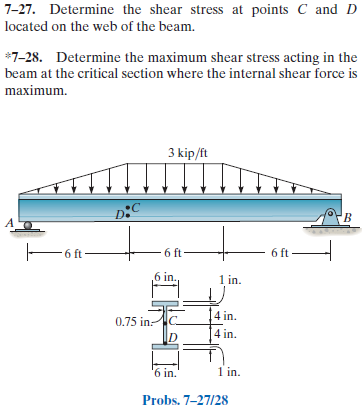

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-27P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-27P-solution-9780136022305) (problem 7-27)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-28P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-28P-solution-9780136022305) (problem 7-28)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1 = findpoly(1, 'thru', [0 0], 'thru', [6*u.ft -3*u.kip/u.ft]);
w2(x) = -3*u.kip/u.ft;
w3 = findpoly(1, 'thru', [12*u.ft -3*u.kip/u.ft], 'thru', [18*u.ft 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 18*u.ft);
b = b.add('distributed', 'force', w1, [0 6]*u.ft);
b = b.add('distributed', 'force', w2, [6 12]*u.ft, [false true]);
b = b.add('distributed', 'force', w3, [12 18]*u.ft, [false true]);
b.L = 18*u.ft;

# section properties

yc = [4+1/2 4/2 -4/2 -4-1/2]*u.in;
Ac = [6*1 0.75*4 0.75*4 6*1]*u.in^2;
Ic = [6*1^3 0.75*4^3 0.75*4^3 6*1^3]/sym(12)*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{36\,x\,\left(x^{4}-720\,x^{2}\,{\mathrm{ft}}^{2}+142560\,{\mathrm{ft}}^{4}\right)}{115\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{216\,\left(5\,x^{4}-180\,x^{3}\,\mathrm{ft}+360\,x^{2}\,{\mathrm{ft}}^{2}+22680\,x\,{\mathrm{ft}}^{3}+1296\,{\mathrm{ft}}^{4}\right)}{115\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{36\,\left(x-18\,\mathrm{ft}\right)\,\left(x^{4}-72\,x^{3}\,\mathrm{ft}+1224\,x^{2}\,{\mathrm{ft}}^{2}+2592\,x\,{\mathrm{ft}}^{3}+14256\,{\mathrm{ft}}^{4}\right)}{115\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{36\,\left(x^{4}-432\,x^{2}\,{\mathrm{ft}}^{2}+28512\,{\mathrm{ft}}^{4}\right)}{23\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{864\,\left(x-9\,\mathrm{ft}\right)\,\left(-x^{2}+18\,x\,\mathrm{ft}+126\,{\mathrm{ft}}^{2}\right)}{23\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{5}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{36\,\left(-x^{4}+72\,x^{3}\,\mathrm{ft}-1512\,x^{2}\,{\mathrm{ft}}^{2}+7776\,x\,{\mathrm{ft}}^{3}+6480\,{\mathrm{ft}}^{4}\right)}{23\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{x\,\left(216\,{\mathrm{ft}}^{2}-x^{2}\right)}{12}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{3\,\left(x^{2}-18\,x\,\mathrm{ft}+12\,{\mathrm{ft}}^{2}\right)}{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{\left(x-18\,\mathrm{ft}\right)\,\left(x^{2}-36\,x\,\mathrm{ft}+108\,{\mathrm{ft}}^{2}\right)}{12}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{72\,{\mathrm{ft}}^{2}-x^{2}}{4}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -3\,\left(x-9\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{x^{2}-36\,x\,\mathrm{ft}+252\,{\mathrm{ft}}^{2}}{4}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{x}{2}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -3\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{x-18\,\mathrm{ft}}{2}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 18\,\mathrm{kip}\\ \mathrm{Rb} & 18\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

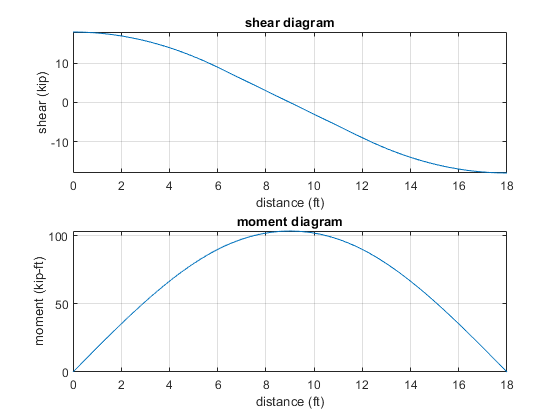

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# shear stress at point C

V_C = v(6*u.ft);
Q_C = sum(Qn(1:2));
b.I = rewrite(b.I, u.in);
t_C = 0.75*u.in;
tau_C = rewrite(V_C*Q_C/(b.I*t_C), u.ksi);
tau_C_vpa = vpa(tau_C, 3) %#ok<NASGU> 

$$tau\_C\_vpa = 1.43\,\mathrm{ksi}$$

# shear stress at point D

V_D = V_C;
Q_D = Qn(1);
t_D = t_C;
tau_D = rewrite(V_D*Q_D/(b.I*t_D), u.ksi);
tau_D_vpa = vpa(tau_D, 3) %#ok<NASGU> 

$$tau\_D\_vpa = 1.17\,\mathrm{ksi}$$

# absolute maximum shear stress

V_max = v(0);
Q_max = Q_C;
t_min = t_C;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.ksi);
tau_max_vpa = vpa(tau_max, 3) %#ok<NASGU> 

$$tau\_max\_vpa = 2.87\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear tau_C_vpa;
clear tau_D_vpa;
clear tau_max_vpa;